Copyright © 2021  Shababuddin Khan  || sk@pcampus.edu.np

*Department of Electrical Engineering, *[Pulchowk Campus](https://pcampus.edu.np/)*, Tribhuwan University, Nepal*

A Series of  Module has been designed and developed by author mentioned above with full copyright for a course of **Control System** to demonstrante the concept of control system and its implementation in real life to second year Aerospace engineering students at Tribhuwan University.

# ***MODULE VIII: Controller Design***

# ***8.1 Design Requirements***

For a 1-rad/sec step reference, the design criteria are the following.                         

- Settling time less than 2 seconds

- Overshoot less than 5%

- Steady-state error less than 1%

# 8.2 System Model

J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;
s = tf('s');
P_motor = K/((J*s+b)*(L*s+R)+K^2);

# 8.3 Review the Characteristics of Original System

It can be done by using Linear System Analyser App of MATLAB.

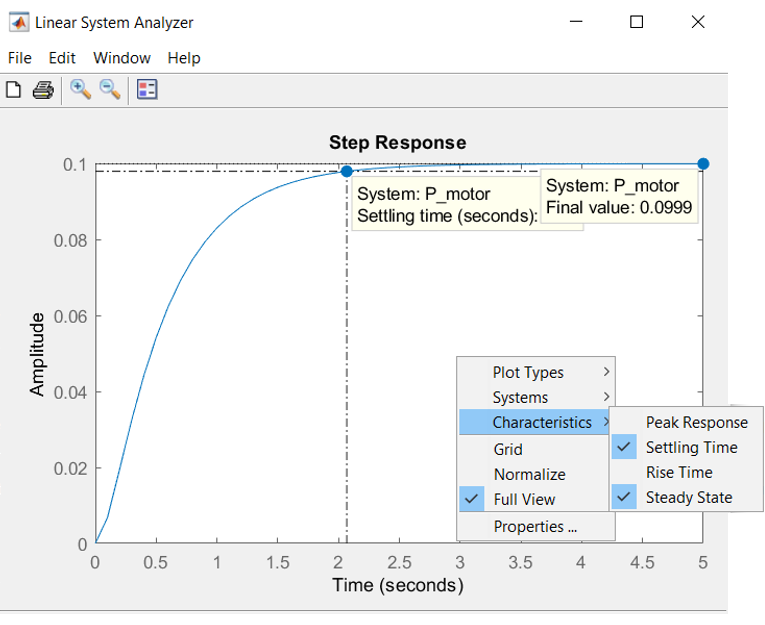

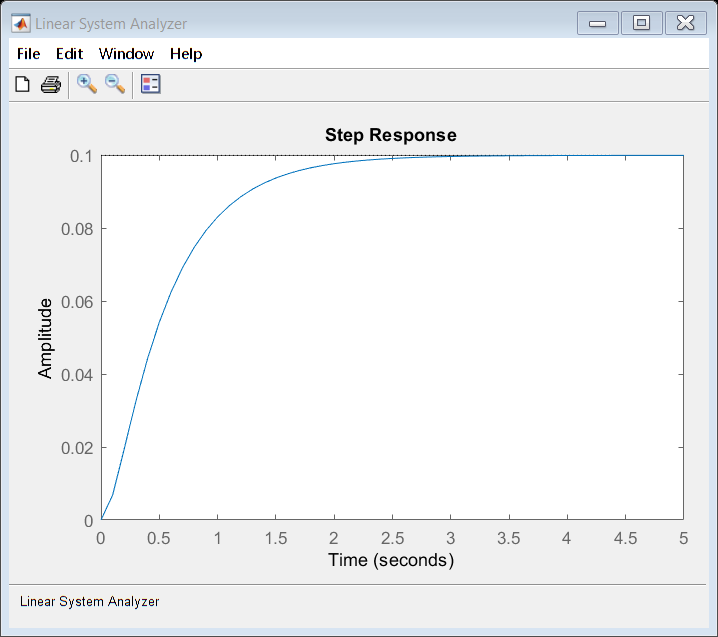

linearSystemAnalyzer('step', P_motor, 0:0.1:5);

From the plot we see that when 1 Volt is applied to the system the motor can only achieve a maximum speed of 0.1 rad/sec, ten times smaller than our desired speed. Also, it takes the  motor 2.07 seconds to reach its steady-state speed; this does not satisfy our 2 second settling time criterion.

# 8.4 Model Analysis and Modification

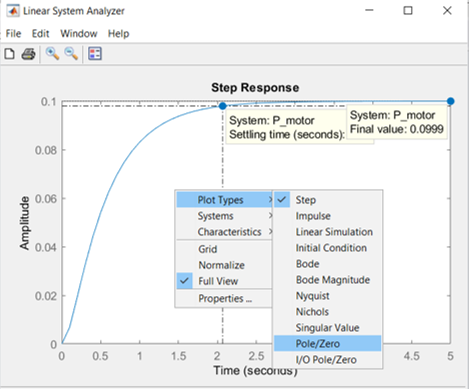

rP_motor = 0.1/(0.5*s+1)


rP_motor =
 
     0.1
  ---------
  0.5 s + 1
 
Continuous-time transfer function.



The open-loop transfer function contains two real poles, one at s = -2 and one at s = -10, as shown above. As we have already seen, there is no oscillation in the step response (or overshoot) because both poles are real. Furthermore, because one pole is 5 times more negative than the other, the dynamics will be dominated by the slower of the two poles. That is, the pole at *s* = -2 primarily determines the speed of response of the system and the system behaves similarly to a first-order system. 

We can check the effectiveness of reduced system by plotting it on the LTI Curve.

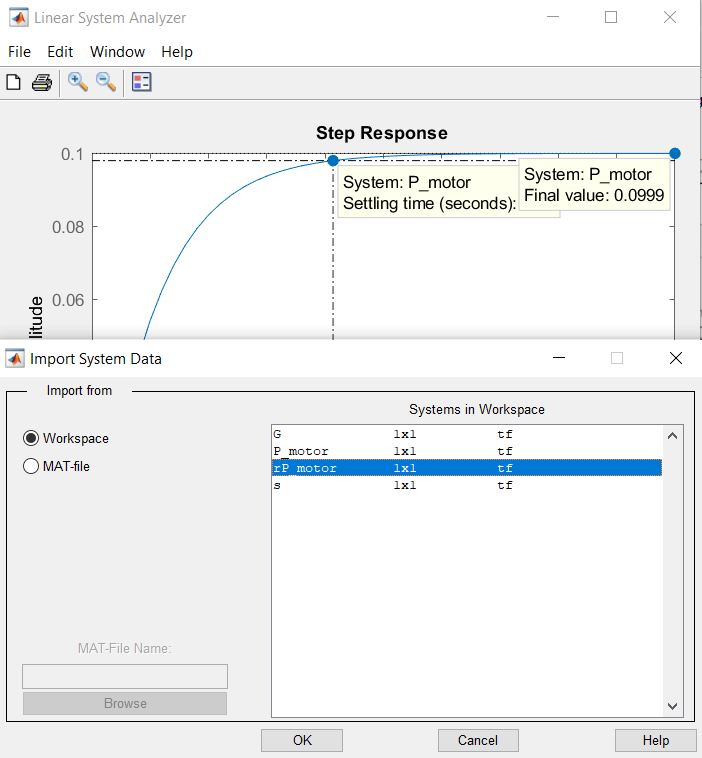

Fig: Importing the reduced transfer function

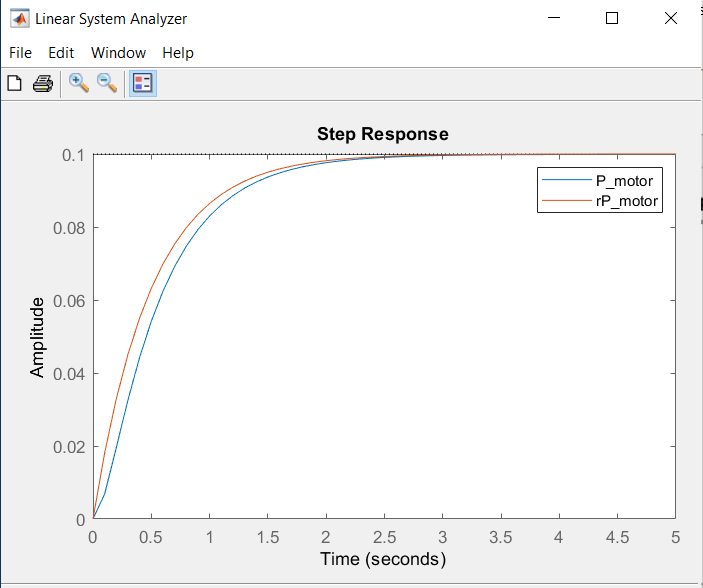

Fig: Output of the system

As  seen from the figure, a first-order approximation of our motor system is fairly accurate. The main distinction is that a second order system will have a derivative of zero at t = 0, but our first-order model will not.

# 8.5 Sine Response of System

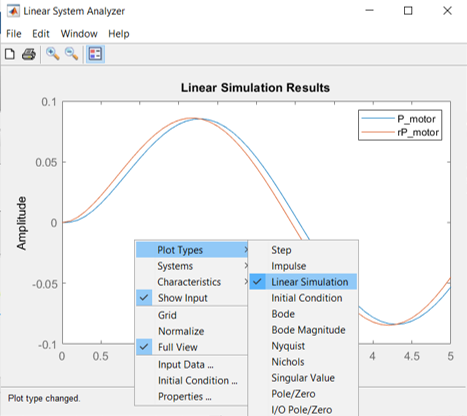

Fig: Jumping to Other Input Signal

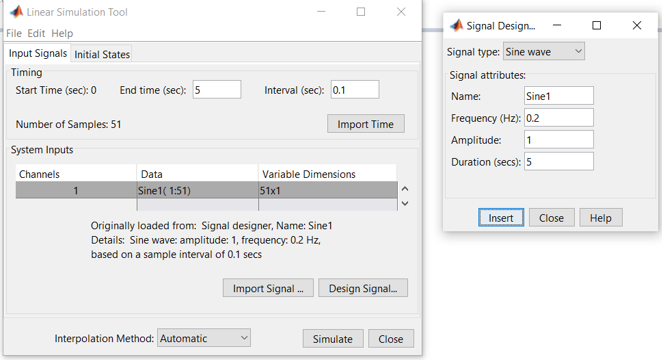

Fig: Design Sinusoidal Input Signal

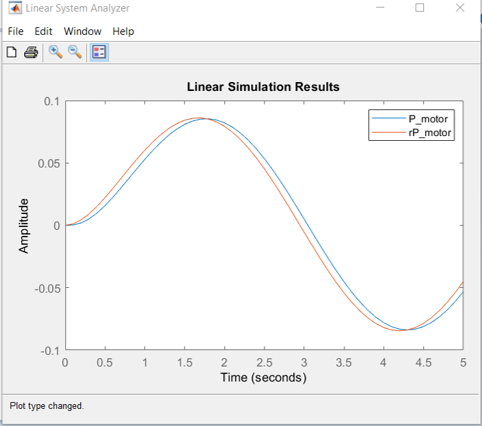

Fig: Sinusoidal Response of the system

# 8.6 Adding a controller

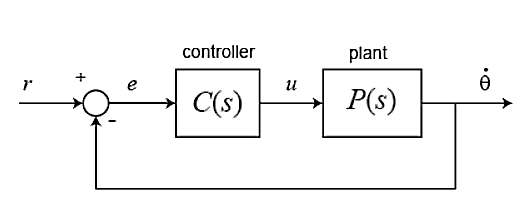

Fig: Adding a Controoler to the System [Closed Loop]

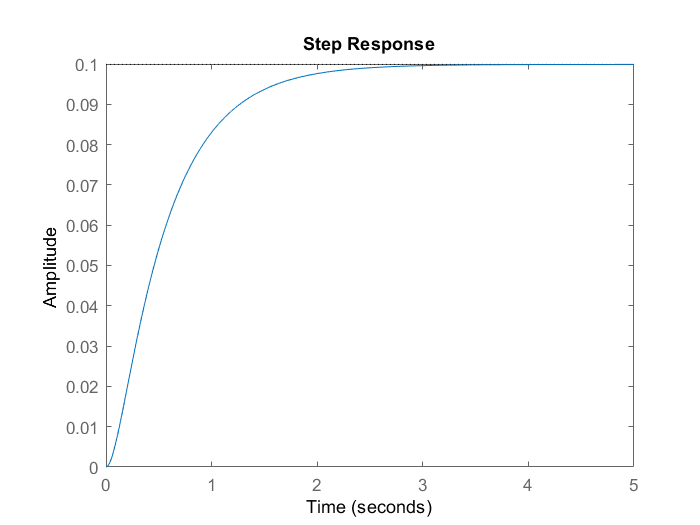

% Taking the system
J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;
s = tf('s');
P_motor = K/((J*s+b)*(L*s+R)+K^2);
t = 0:0.01:5;
step(P_motor,t);


% Addition of COntroller
Kp = 1;
Ki = 1;
Kd = 1;
C = pid(Kp,Ki,Kd);                           % Defining the Controller
sys_controller = feedback(C*P_motor,1)     % With Unity Feedback


sys_controller =
 
         0.01 s^2 + 0.01 s + 0.01
  --------------------------------------
  0.005 s^3 + 0.07 s^2 + 0.1101 s + 0.01
 
Continuous-time transfer function.



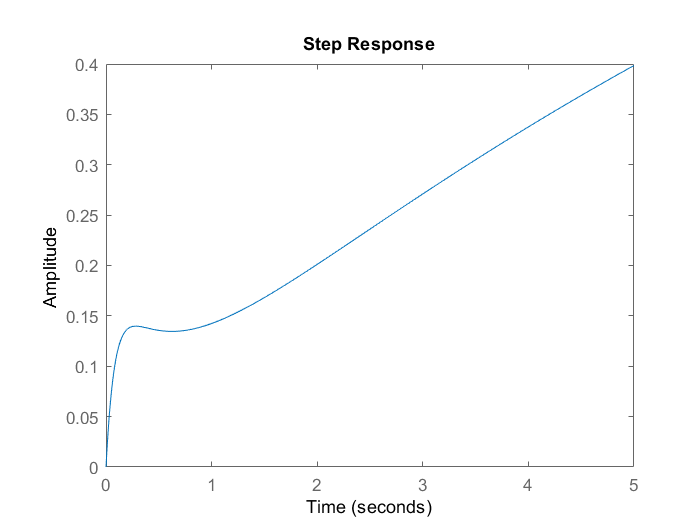

t = 0:0.01:5;
step(sys_controller,t);

# 8.7 Tuning PID controller

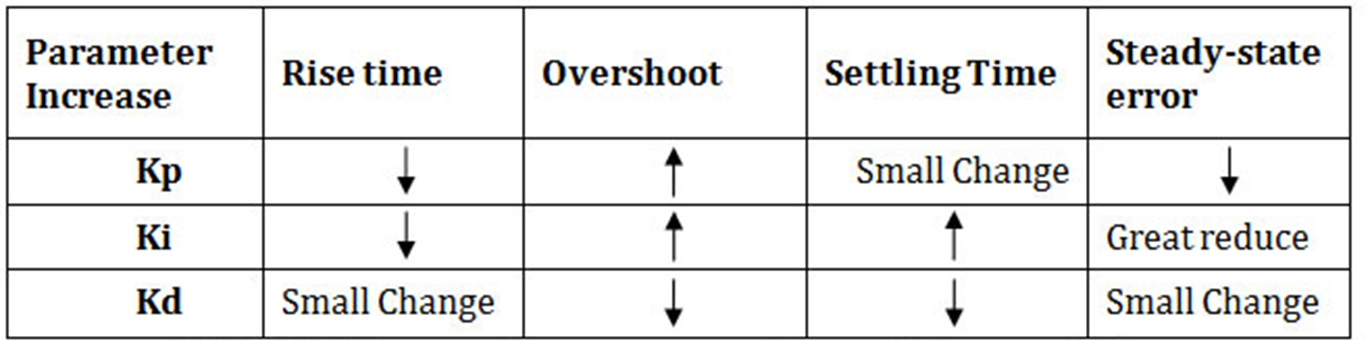

Kp = 100;
Ki = 200;
Kd = 10;
C = pid(Kp,Ki,Kd);                           % Defining the Controller
sys_controller = feedback(C*P_motor,1)     % With Unity Feedback


sys_controller =
 
          0.1 s^2 + s + 2
  --------------------------------
  0.005 s^3 + 0.16 s^2 + 1.1 s + 2
 
Continuous-time transfer function.



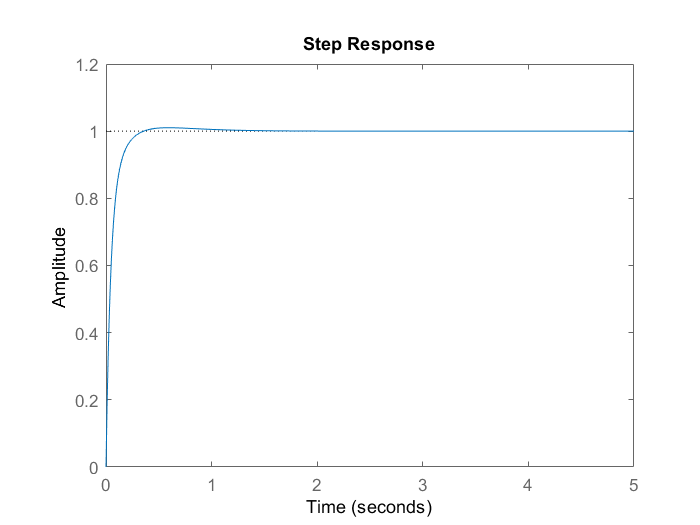

t = 0:0.01:5;
step(sys_controller,t);

%To Get Transient Response Data
S=stepinfo(sys_controller)

S = struct with fields:
        RiseTime: 0.1324
    SettlingTime: 0.2570
     SettlingMin: 0.9010
     SettlingMax: 1.0103
       Overshoot: 1.0281
      Undershoot: 0
            Peak: 1.0103
        PeakTime: 0.5932



%Steady State Error
SP=1; %input value, if you put 1 then is the same as step(sys)
[y,t]=step(SP*sys_controller); %get the response of the system to a step with amplitude SP
sserror=abs(SP-y(end)) %get the steady state error

sserror = 5.9931e-05

# 8.8 Controller Design using Control System Designer App

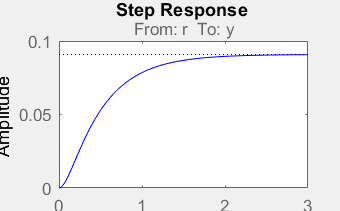

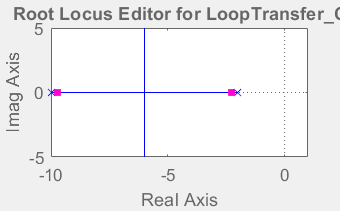

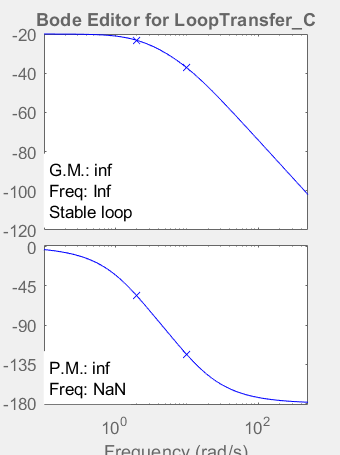

% Taking the system
J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;
s = tf('s');
P_motor = K/((J*s+b)*(L*s+R)+K^2);
%Open Control System Designer App
controlSystemDesigner(P_motor);

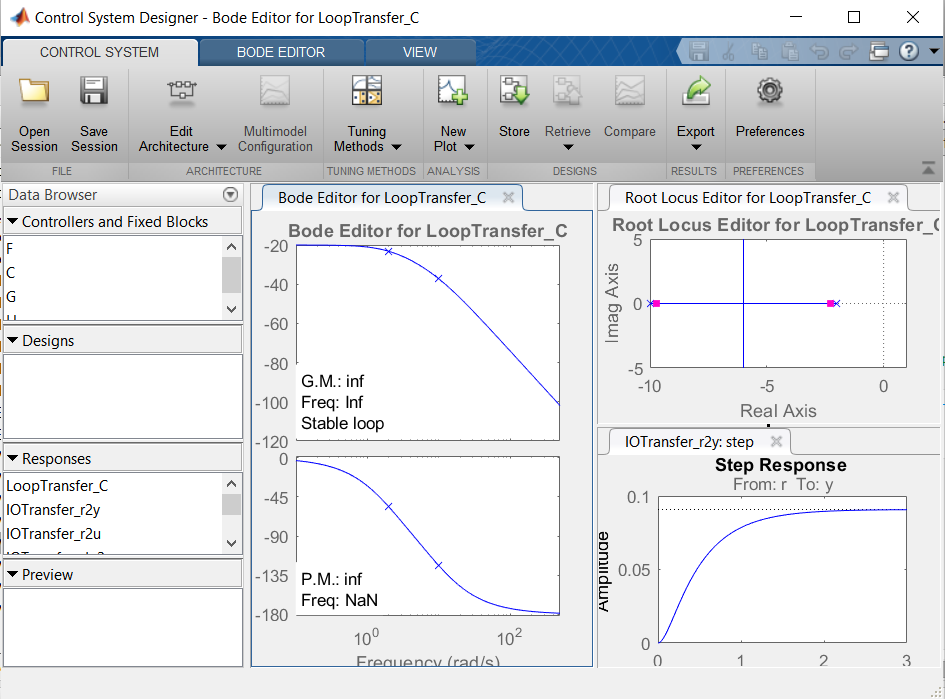

Fig: Control System Designer

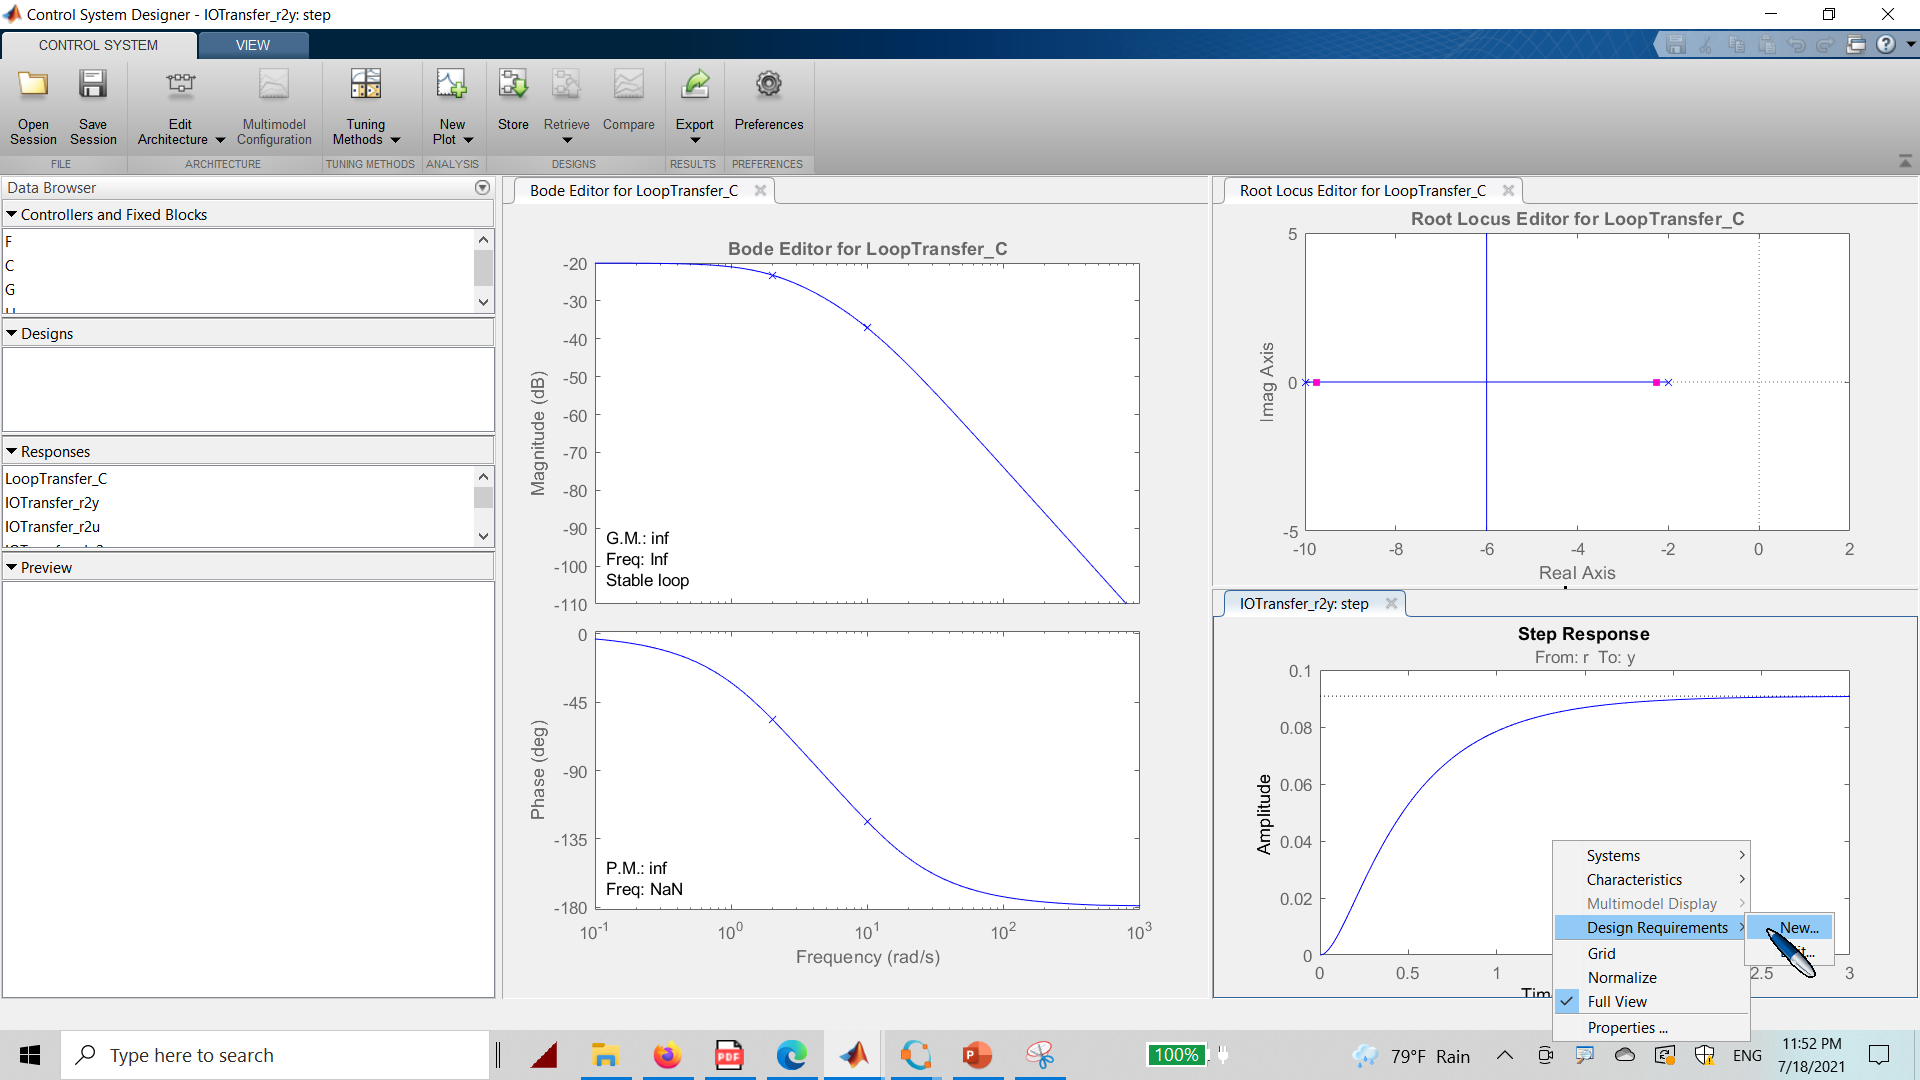

Fig: Setting the Design Requirements

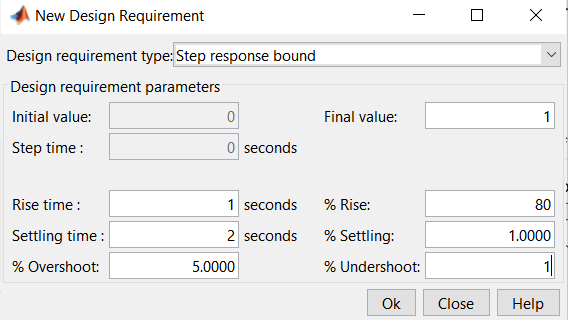

Fig: Assiging the Design Requirements

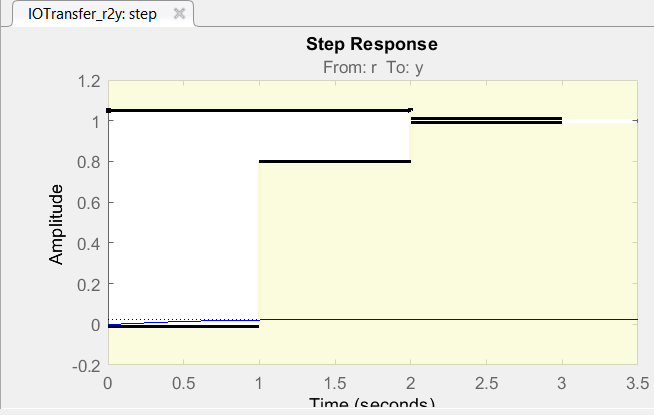

Fig: Valid and Invalid Regions

Tune the values of controller to bring them to the valid region by changing Kp, Ki and Kd.

# 8.9 Lag Bode Controller Design 

%Given
s=tf('s');
G=1/(s*(s+2)*(s+20));
kv=20;
pm=35;

%  Step 1: Find value of K using static velocity error constant
k=kv/dcgain(s*G);

%  Step 2: Draw bode plot for uncompensated system
G1=k*G;
bode(G1)
hold on
%
%% 
%  Step 3: Phase margin = Desired/Given  phase margin + safety margin
e=5;
phi = pm + e

phi = 40


%  Step 4: Obtain required gcf(wm) for Pm3
phi = phi - 180 

phi = -140

wm = 2; % see graph and obtain frequency value wm correspondind to pm3

% Step 5: Attenuation Constant(a)
M = 20;% see graph and obtain magnitude for wm=2
a = 10^(M/-20)%Attenuation constant

a = 0.1000


% Step 6: Calculation of T
T = 10/(a*wm)

T = 50


% Step 7: Transfer function of compensator
Gc = (1+a*T*s)/(1+T*s)


Gc =
 
  5 s + 1
  --------
  50 s + 1
 
Continuous-time transfer function.




% Step 8: Overall Transfer function of the system
Go = G1*Gc


Go =
 
             4000 s + 800
  -----------------------------------
  50 s^4 + 1101 s^3 + 2022 s^2 + 40 s
 
Continuous-time transfer function.



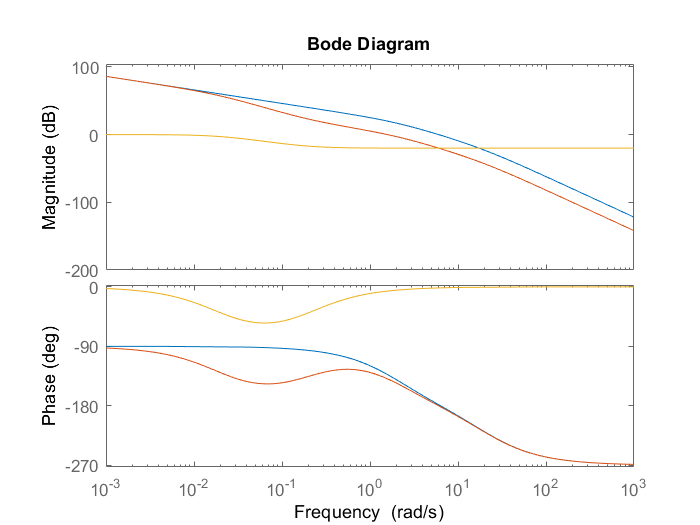


% Step 9: Bode plot for overall compensated system Go
bode(Go)
hold on 
bode(Gc)
hold off

# 8.10 Lead Bode Controller Design 

%Given
s=tf('s');
G=1/(s*(1+0.1*s)*(1+0.001*s));
kv=1000;
pm_s=45;

%  Step 1: Find value of K using static velocity error constant
k=kv/dcgain(s*G);

%  Step 2: Draw bode plot for uncompensated system
G1=k*G;
bode(G1)
hold on

%
%% 
%  Step 3: Phase margin = Desired/Given  phase margin + safety margin
e=5;
pm=0 %see graph for phase margin 

pm = 0

phi = pm_s - pm + e

phi = 50

%Note if phi<60 or not

% Step 4: Attenuation Constant(a)
a = (1+sin(phi))/(1-sin(phi));%  Attenuation constant

%  Step 5: Obtain required gcf(wm) for M
M= -10*(log10(a))

M = 2.3335

wm = 170; % see graph and obtain frequency value wm correspondind to M

% Step 6: Calculation of T
T = 1/(wm*sqrt(a))

T = 0.0077


% Step 7: Transfer function of compensator
Gc = (1+a*T*s)/(1+T*s)


Gc =
 
  0.004497 s + 1
  --------------
  0.007695 s + 1
 
Continuous-time transfer function.




% Step 8: Overall Transfer function of the system
Go = G1*Gc


Go =
 
                  4.497 s + 1000
  ----------------------------------------------
  7.695e-07 s^4 + 0.0008772 s^3 + 0.1087 s^2 + s
 
Continuous-time transfer function.



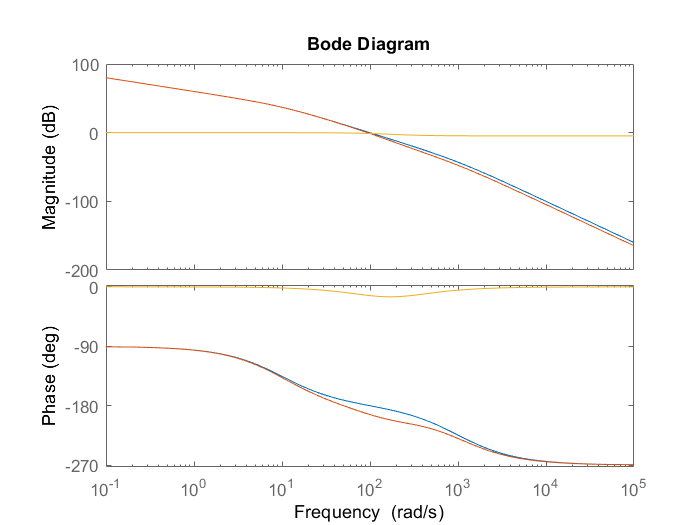


% Step 9: Bode plot for overall compensated system Go
bode(Go)
hold on 
bode(Gc)
hold off

# References

- Mathworks.inc

- Nise, Norman S. "Control system engineering, John Wiley & Sons." *Inc, New York*(2011).

- [https://ctms.engin.umich.edu/CTMS/index.php?aux=Home](https://ctms.engin.umich.edu/CTMS/index.php?aux=Home)

- Bakshi, Uday A., and Varsha U. Bakshi. *Control system engineering*. Technical Publications, 2020.